function meanP1 = simulateP1(F_0_val, p1_real_val)

% Space out points on the x-axis 
% Starting from 12.5 up to 256.
t = linspace(12.5/256, 12.5, 256)';

% Decays are biologically fixed
tau1 = 2.14; 
tau2 = 0.69;

% Compute the column vectors of the A matrix 
a1 = exp(-t / tau1);
a2 = exp(-t / tau2);

% IRF centered at 2ns
mu = 2;

% Full with half max = 340ps (defining Gaussian for IRF)
fwhm = 0.34;

% Convert FWHM to standard deviation using known formula
% FWHM = 2 * sigma * sqrt{2 ln(2)}
sigma = fwhm / (2*sqrt(2*log(2)));

% Define IRF using Gaussian standard deviation formula
% Evenly space points
irf = exp(-(t - mu).^2 / (2*sigma^2));
irf = irf / sum(irf);

% Apply convolution to each vector of A
% 'Same' ==> we get col vector of length 256
a1_conv = conv(a1, irf, 'same');
a2_conv = conv(a2, irf, 'same');

% A matrix stores the decay factors
A = [a1_conv, a2_conv];

% Number of photons (F_sensor)
F_0 = F_0_val;

% Ground truth P1 value
p1_real = p1_real_val;
p2_real = 1-p1_real;

% Components of c matrix
c1 = F_0*p1_real;
c2 = F_0*p2_real;

% Composed of F0P1 and F0P2
c = [c1,c2]';

% Gives: ideal distribution = F0P1e^{-t/tau1}+F0P2e^{-t/tau2}
ideal = A * c;

% Probability distribution over each histogram bucket
prob = ideal / sum(ideal);

% Constructing the AutoFlourescense curve
F_autoF = 4560;
tau_autoF = 1.69;
a_autoF = exp(-t / tau_autoF);
a_autoF_conv = conv(a_autoF, irf, 'same');
prob_autoF = a_autoF_conv / sum(a_autoF_conv);


% Constructing the Background & part of afterpulse curve
F_background = 3484;
F_afterpulse = F_0 * 0.0032;
prob_flat = ones(256,1)/256;

%A = [a1,a2];


% Build the full basis once and SVD it
A_full = [a1_conv, a2_conv, a_autoF_conv, ones(256,1)];
[U, S, V] = svd(A_full, 'econ');
s = diag(S);
s_inv = 1 ./ s;
% drop two smallest sv's
s_inv(end-1:end) = 0;       


% disp(s')
% disp(s(1)/s(end))   % condition number

p1_estimates = zeros(500, 1);
for k = 1:500

% Populates buckets according to given probability
% Distribution is multinomial
y_sensor = mnrnd(F_0, prob)';
y_autoF = mnrnd(F_autoF, prob_autoF)';
y_background = mnrnd(F_background, prob_flat)';
y_afterpulse = mnrnd(round(F_afterpulse), prob_flat)';

y = y_sensor + y_autoF + y_background + y_afterpulse;


c_hat = V * (s_inv .* (U' * y));

c1_hat = c_hat(1);
c2_hat = c_hat(2);
P1_hat = c1_hat / (c1_hat + c2_hat);       

p1_estimates(k) = P1_hat;  


% % Pseudoinverse * y = Fitted F0P1 and F0P2
% c_hat =(inv(A' * A)*A')*y;
% 
% % Compute fitted values
% c1_hat = c_hat(1);
% c2_hat = c_hat(2);
% P1_hat = c1_hat / (c1_hat + c2_hat);
% 
% p1_estimates(k) = P1_hat;  


end
   meanP1 = median(p1_estimates);
end

F0_vals = 100000:10000:800000;
p1_vals = 0.40:0.01:0.60;

results = zeros(length(F0_vals),length(p1_vals));

for i = 1:length(F0_vals)

    F0 = F0_vals(i);

    for j = 1:length(p1_vals)

        P1 = p1_vals(j);

        results(i,j) = simulateP1(F0,P1);

    end
end

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277    0.0010

   1.5689e+04

   16.0048    0.5795    0.0277 

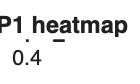



figure;
imagesc(p1_vals, F0_vals, results);
clim auto;
colorbar;
xlabel('Simulated P1');
ylabel('Sensor photons');
title('Fitted P1 heatmap');
set(gca, 'YDir', 'normal');